**Student Name:** Naman Shah

**Last 4 Digits of RUID:** 8939

**Section:** C1

**Math 250 MATALB Assignment:** 2

rand('seed', 8939)

**Question 1: **Row Operations and LU Factorization

(1)(a) 

A = rand(3)

A =     0.8930    0.6138    0.6400
    0.2642    0.5855    0.9990
    0.1842    0.8534    0.7517


A(1, 1)

ans = 0.8930

det(A(1:2, 1:2))

ans = 0.3606

det(A)

ans = -0.3020

U = A

U =     0.8930    0.6138    0.6400
    0.2642    0.5855    0.9990
    0.1842    0.8534    0.7517


col1

L1 =     1.0000         0         0
   -0.2959    1.0000         0
   -0.2063         0    1.0000


The row operations in `col1.m` transform matrix U into an upper triangular form.

The first row is kept intact while the multiples of the first row's elements are subtracted from the corresponding rows below. 

The first column below the main diagonal of U contains zeros. The resulting matrix L1 is unit lower triangular with non-zero entries only on the diagonal and in the first column. 

(1)(b)

U = L1*A

U =     0.8930    0.6138    0.6400
         0    0.4038    0.8096
         0    0.7268    0.6197


col2

L2 =     1.0000         0         0
         0    1.0000         0
         0   -1.7998    1.0000


U = L2*U

U =     0.8930    0.6138    0.6400
         0    0.4038    0.8096
         0         0   -0.8374


The row operations in `col2.m` modify matrix U to have all zeros below the main diagonal, focusing on the second column. 

The first two rows remain unchanged while a multiple of the second row's elements is subtracted from the third row. 

The second column below the main diagonal of U contains zeros. The resulting matrix L2 is unit lower triangular.

L2*L1*A

ans =     0.8930    0.6138    0.6400
         0    0.4038    0.8096
    0.0000   -0.0000   -0.8374


U

U =     0.8930    0.6138    0.6400
         0    0.4038    0.8096
         0         0   -0.8374


Both of these matrices are the same.

(1)(c)

iL1 = inv(L1)

iL1 =     1.0000         0         0
    0.2959    1.0000         0
    0.2063         0    1.0000


iL2 = inv(L2)

iL2 =     1.0000         0         0
         0    1.0000         0
         0    1.7998    1.0000


L = iL1*iL2

L =     1.0000         0         0
    0.2959    1.0000         0
    0.2063    1.7998    1.0000


Yes the column 1 of L is the same as column 1 of iL1 and the column 2 of L is the same as the column 2 of iL2

A

A =     0.8930    0.6138    0.6400
    0.2642    0.5855    0.9990
    0.1842    0.8534    0.7517


L*U

ans =     0.8930    0.6138    0.6400
    0.2642    0.5855    0.9990
    0.1842    0.8534    0.7517


A == L*U

ans = 3×3 logical array
   1   1   1
   1   1   1
   1   1   1


Yes, both the matrices are the same.

**Question 2: **Using LU Factorization to Solve Ax = b

(2)(a)

The formula for inv(L) is L2*L1 because L = inv(L1)*inv(L2).

The identity goes like:

L^-1 = (L1^-1 * L2^-1)^-1 = L2*L1

inv(L)

ans =     1.0000         0         0
   -0.2959    1.0000         0
    0.3263   -1.7998    1.0000


inv(U)

ans =     1.1198   -1.7022   -0.7898
         0    2.4763    2.3942
         0         0   -1.1942


Yes, both of these matrices are in triangular form.

L is a lower triangular matrix, while U is an upper triangular matrix.

(2)(b)

b = rvect(3)

b =      6
     6
     4


c = inv(L)*b

c =     6.0000
    4.2245
   -4.8411


x = inv(U)*c

x =     3.3515
   -1.1291
    5.7814


A*x

ans =     6.0000
    6.0000
    4.0000


b

b =      6
     6
     4


Yes, Ax = b, both these vectors have the values 6, 6 and 4.

**Question 3: **Speed comparison of *LU* versus rref for showing *A****x****=****b***

A = rand(500);
b = rand(500, 1);
[L U] = lu(A);

(3)(a)

tic;
R = rref([A b]);
y = R(:, 501);
toc

Elapsed time is 2.572556 seconds.


Elapsed time is about 2.5 seconds

(3)(b)

tic;
c = inv(L)*b;
x = inv(U)*c;
toc

Elapsed time is 0.023108 seconds.


Elapsed time is about 0.03 seconds

We can see that LU decomposition takes way faster to solve matrices

norm(x-y)

ans = 1.1472e-12

The error is almost negligible.

(3)(c)

Gaussian elimination = 2c(n^3)/3

LU method = 2c(n^2)/3

(3)(c)(i)

n = 500

ratio = (2(c)(500^3)/3)/(2(c)(500^2)/3)

= 500

(3)(c)(ii)

ratio = (2.439411)/(0.02769) = 88.0971830986 === 88.1

**Question 4: **The determinant function

(4)(a)

a = rmat(4,4)

A =      1     4     2     6
     0     6     1     6
     7     2     7     8
     3     2     5     1


a =      1     4     2     6
     0     6     1     6
     7     2     7     8
     3     2     5     1


c = cofactor(a)

c =  -208.0000 -101.0000  150.0000   76.0000
  128.0000   85.0000 -102.0000  -44.0000
   64.0000   11.0000  -42.0000   -4.0000
  -32.0000    8.0000   48.0000  -16.0000


a(1,1)*c(1,1) + a(1,2)*c(1,2) + a(1,3)*c(1,3) + a(1,4)*c(1,4)

ans = 144

a(2,1)*c(2,1) + a(2,2)*c(2,2) + a(2,3)*c(2,3) + a(2,4)*c(2,4)

ans = 144.0000

a(1,3)*c(1,3) + a(2,3)*c(2,3) + a(3,3)*c(3,3) + a(4,3)*c(4,3)

ans = 144.0000

a(1,4)*c(1,4) + a(2,4)*c(2,4) + a(3,4)*c(3,4) + a(4,4)*c(4,4)

ans = 144.0000

All sums give the same number, 144, as that is the determinant of the matrix A

Theorem 3.1 from the textbook tells us that the the determinant of a nxn matrix can be calculated using a cofactor expansion along any row.

- The first sum represents cofactor expansion along the first row

- The second sum represents cofactor expansion along the second row

Theorem 3.4 tells us that the determinant of any nxn matrix is equal to the determinant of the transpose of the original matrix.

Because the columns of the matrix are equal to the rows of its transpose:

- The third sum represents the cofactor expansion along the first column (first row of a^T)

- The fourth sum represents the cofactor expansion along the second column (second row of a^T)

(4)(b)

A = rmat(5,5)

A =      8     8     3     1     4
     3     1     8     4     3
     1     2     3     6     0
     6     1     7     5     9
     5     7     0     9     2


A =      8     8     3     1     4
     3     1     8     4     3
     1     2     3     6     0
     6     1     7     5     9
     5     7     0     9     2


U = triu(A)

U =      8     8     3     1     4
     0     1     8     4     3
     0     0     3     6     0
     0     0     0     5     9
     0     0     0     0     2


A(1,1)*A(2,2)*A(3,3)*A(4,4)*A(5,5)

ans = 240

U(1,1)*U(2,2)*U(3,3)*U(4,4)*U(5,5)

ans = 240

Both of these values for me are 240. Yes, we can calculate the determinant using this information.

However, we cannot obtain det(A) by just multiplying the diagonal entries, but we can using U or the upper triangular matrix.

We know for any matrix that is an upper triangular matrix, and the determinant of an upper or lower triangular matrix is the product of its diagonal matrix.

det(A)

ans = 673.0000

det(U)

ans = 240

As suspected, the determinant of U is correct as U(1,1)*U(2,2)*U(3,3)*U(4,4)*U(5,5), while that is not the case for A

(4)(c)

A = rmat(5,5)

A =      6     9     2     8     4
     7     0     3     6     7
     9     4     9     2     7
     5     9     1     9     2
     7     0     4     6     2


A =      6     9     2     8     4
     7     0     3     6     7
     9     4     9     2     7
     5     9     1     9     2
     7     0     4     6     2


B = A;
B(2,:) = A(1,:)

B =      6     9     2     8     4
     6     9     2     8     4
     9     4     9     2     7
     5     9     1     9     2
     7     0     4     6     2


B(1,:) = A(2,:)

B =      7     0     3     6     7
     6     9     2     8     4
     9     4     9     2     7
     5     9     1     9     2
     7     0     4     6     2


(4)(c)(i)

Since we performed a row interchange between the two rows from A, the relationship between A and B will be this:

- det(A) = -det(B)

det(A)

ans = 1.3300e+03

det(B)

ans = -1.3300e+03

det(A) == -det(B)

ans = logical
   1


Yes, our assumption was correct

(4)(c)(ii)

C = A;
C(2,:) = A(2,:) + 10*A(1,:)

C =      6     9     2     8     4
    67    90    23    86    47
     9     4     9     2     7
     5     9     1     9     2
     7     0     4     6     2


C

C =      6     9     2     8     4
    67    90    23    86    47
     9     4     9     2     7
     5     9     1     9     2
     7     0     4     6     2


We perfomed added a multiple of another row onto an existing row. According to the properties of the determinants, the determinant remains unchanged

det(A) = det(C)

det(A)

ans = 1.3300e+03

det(C)

ans = 1.3300e+03

det(A) == det(C)

ans = logical
   0


Yes, our assumption was correct.

(4)(c)(iii)

D = A;
D(1,:) = 10*A(1,:)

D =     60    90    20    80    40
     7     0     3     6     7
     9     4     9     2     7
     5     9     1     9     2
     7     0     4     6     2


D

D =     60    90    20    80    40
     7     0     3     6     7
     9     4     9     2     7
     5     9     1     9     2
     7     0     4     6     2


We multiplied row 1 with a scalar k, this means the relationship between the determinants of D and A looks like:

- det(A) = (1/k)*det(D)

Since the scalar here is 10

- det(A) = 0.1(det(D))

- 10*det(A) = det(D)

- det(10*A) = det(D)

det(A)

ans = 1.3300e+03

det(D)

ans = 1.3300e+04

det(A) == 0.1*det(D)

ans = logical
   0


det(A) == det(0.1*D)

ans = logical
   0


10*det(A) == det(D)

ans = logical
   0


det(10*det(A)) == det(D)

ans = logical
   0


(4)(d)

A = rmat(5,5)

A =      5     3     9     9     0
     8     6     4     2     3
     6     1     3     2     6
     1     8     2     7     8
     4     0     1     8     0


A =      5     3     9     9     0
     8     6     4     2     3
     6     1     3     2     6
     1     8     2     7     8
     4     0     1     8     0


A(1,1) = 0

A =      0     3     9     9     0
     8     6     4     2     3
     6     1     3     2     6
     1     8     2     7     8
     4     0     1     8     0


A(2,1) = 0

A =      0     3     9     9     0
     0     6     4     2     3
     6     1     3     2     6
     1     8     2     7     8
     4     0     1     8     0


A

A =      0     3     9     9     0
     0     6     4     2     3
     6     1     3     2     6
     1     8     2     7     8
     4     0     1     8     0


[P, L, U, sign] = splu(A)

P =      0     0     1     0     0
     0     1     0     0     0
     1     0     0     0     0
     0     0     0     1     0
     0     0     0     0     1


L =     1.0000         0         0         0         0
         0    1.0000         0         0         0
         0    0.5000    1.0000         0         0
    0.1667    1.3056   -0.5317    1.0000         0
    0.6667   -0.1111   -0.0794    0.9054    1.0000


U =     6.0000    1.0000    3.0000    2.0000    6.0000
         0    6.0000    4.0000    2.0000    3.0000
         0         0    7.0000    8.0000   -1.5000
         0         0         0    8.3095    2.2857
         0         0         0         0   -5.8553


sign = -1

PA = LU

P: permutation matrix expressing row interchanges

LU is the LU decompostion

Sign is -1, meaning there have odd number of row exchanges.

r3 <-> r1

This is the only row exchange apparrent from P, meaning 1 row interchange, which is an odd number.

P*A

ans =      6     1     3     2     6
     0     6     4     2     3
     0     3     9     9     0
     1     8     2     7     8
     4     0     1     8     0


L*U

ans =     6.0000    1.0000    3.0000    2.0000    6.0000
         0    6.0000    4.0000    2.0000    3.0000
         0    3.0000    9.0000    9.0000         0
    1.0000    8.0000    2.0000    7.0000    8.0000
    4.0000         0    1.0000    8.0000         0


Yes both matrices are the same.

(4)(d)(i)

det(P) = -1

This is because the P represents the identity matrix, whose determinant is 1. Since we performed 1 row interchange, det(In) = -det(P), making the determinant of P, -1.

det(P)

ans = -1

Our assumption was correct

(4)(d)(ii)

det(L) = 1

All the diagonal entries in the lower triangular matrix are 1, meaning the determinant would be the product of these matrices, making it 1.

det(L)

ans = 1.0000

Our assumption was correct.

(4)(d)(iii)

detA and detU have this relationship:

- detA = - detU

This is because Matrix U is obtained by interchanging one row of Matrix A. By properties of determinants, if Matrix U is obtained by interchanging a row of matrix A, then detA = - detU

det(A)

ans = 12261

det(U)

ans = -12261

det(A) == -det(U)

ans = logical
   1


Our assumption was correct

**Question 5: **Geometry and Matrices

H = house;
plot2d(H)

(5)(a)

t = pi/6

t = 0.5236

Q = [cos(t), -sin(t); sin(t), cos(t)]

Q =     0.8660   -0.5000
    0.5000    0.8660


plot2d(Q*H)

(5)(a)(i)

The house changes by rotating by 30 degrees to the left.

(5)(a)(ii)

det(Q)

ans = 1

The determinant is 1. 

This means the are inside the rotated house is equal to the area of the original house.

(5)(a)(iii)

t = -pi/3

t = -1.0472

Q = [cos(t), -sin(t); sin(t), cos(t)]

Q =     0.5000    0.8660
   -0.8660    0.5000


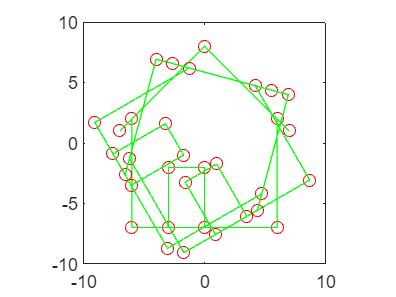

plot2d(Q*H)